# This is the project's main file.

clear variables;
close all;
clc;

## Path initialization

kicker file

camerasTxtFile = '.\kicker_dslr_undistorted\kicker\dslr_calibration_undistorted\cameras.txt';
imagesTxtFile = '.\kicker_dslr_undistorted\kicker\dslr_calibration_undistorted\images.txt';
pointsTxtFile = '.\kicker_dslr_undistorted\kicker\dslr_calibration_undistorted\points3D.txt';
imagesFolder = '.\kicker_dslr_undistorted\kicker\images\dslr_images_undistorted';

Delivery file

camerasTxtFile2 = '.\delivery_area_dslr_undistorted\delivery_area\dslr_calibration_undistorted\cameras.txt';
imagesTxtFile2 = '.\delivery_area_dslr_undistorted\delivery_area\dslr_calibration_undistorted\images.txt';
pointsTxtFile2 = '.\delivery_area_dslr_undistorted\delivery_area\dslr_calibration_undistorted\points3D.txt';
imagesFolder2 = '.\delivery_area_dslr_undistorted\delivery_area\images\dslr_images_undistorted';

## Load necessary files

Obtain necessary camera and image parameters from the txt files

Cameras = loadCameras(string(camerasTxtFile2));
[imagesDS, imageParams, orderedKeys, loadedImages] = loadImages(imagesFolder2, ...
                                                     imagesTxtFile2, ...
                                                     'isDebugFile', true, ...
                                                     'loadNow', true);

## Feature Extraction

Extract features of the image

intrinsics = Cameras(0).intrinsics;
border = 50;
n = numel(imagesDS.Files);

% Store the extract features of each image
features_array = cell(1, n);

for j = 1:numel(imagesDS.Files)
    container = struct;
    I = undistortImage(im2gray(loadedImages(orderedKeys{j})), intrinsics);

    % downsample the image to speed up calculations
    % I = downsample(I,2);
    loadedImages(orderedKeys{j}) = I;

    r = [border, border, size(I,2) - 2* border, size(I,1) - 2*border];

    % Detect and extract features
    currPoints = detectSURFFeatures(I, NumOctaves=8, ROI=r); % Other feature extraction method can be used
    container.features = extractFeatures(I, currPoints);
    container.id = j; % Identifier based on order of images in folder
    container.points = currPoints;
    features_array{j} = container;
end

## Features Matching

Match found features with each other. The goal of this process is to find the next image with the highest number of matching features. Reason: If the image are done sequentially without feature matching, the process might fail as only a small number of features are found

features_array_copy = features_array; %copy features array in case we need to modify it

% An array containing all the matching features of each image pair
% e.g. index 1,2 --> number of matching features between image 1 and 2
matching_features_array = cell(n,n);

For each extracted features, we find matching features for each corresponding pair and find the one with the largest number of matches

The sequence for this can then be: e.g. start with image number 1 and continue with image number 6 (image number 6 has the most matches with image number 1). After that continue with image number 8 as image 8 has the most matches with number 6 until all images are processed. Therefore the loop need to take care of two things:

- Find the highest number of match

- The pair has to be unprocessed/was not previously used --> e.g. image 2 to image 3 and again to image 2 is false

% Matrix creation
for i = 1:n
    for j = 1:n
        % find number of matches for each pair
        prev_features = features_array{i}.features;
        curr_features = features_array{j}.features;
        feature_matches = matchFeatures(prev_features, curr_features, MaxRatio = 0.7, Unique=true);
        
        % Store the number of matches in the matrix
        matching_features_array{i,j} = feature_matches;
    end
end

[number_of_matches, ~] = cellfun(@size,matching_features_array);
number_of_matches = number_of_matches - diag(diag(number_of_matches)); % convert diagonal to 0 because we dont need it.

## Point Cloud generation

Now that we have stored all the matching features in a cell array and also prepared another array to check out the number of matches for each image pair, we are ready to start generating the point cloud.

% Initialization
vSet = imageviewset;
processed_features_array = zeros(1, n); % used to check if image was previously processed

% Take first image of the array
prevStruct = features_array{1};
prevFeatures = prevStruct.features;
prevPoints = prevStruct.points;
prevID = prevStruct.id;

vSet = addView(vSet, prevID, rigidtform3d, Points=prevPoints);

processed_features_array(1) = prevID;


for x = 2:n    
    % Get the most matches found from the first image
    matches_vector = number_of_matches(prevID,:);
    sorted_matches_vector = sort(matches_vector, 'descend');
    
    % Get the largest element of the vector
    % if largest pair processed already -> get 2nd largest and so on until we find an
    % unprocessed image
    counter = 1;
    while 1
        largest_element = sorted_matches_vector(counter);
        index = find(matches_vector==largest_element);
        counter = counter + 1;
        if ~any(processed_features_array(:) == index(1))
            break;
        end
    end
    
    % Save the details of the next image in a new variable
    currStruct = features_array{index};
    currFeatures = currStruct.features;
    currID = currStruct.id;
    currPoints = currStruct.points;

    matching_features = matching_features_array{prevID,currID};
    
    matchedPoints1 = prevPoints(matching_features(:,1));
    matchedPoints2 = currPoints(matching_features(:,2));
    
    % This part may fail with forward matching
    % solution if failed try backward matching
    try
        [relPose, inlierIdx] = helperEstimateRelativePose(matchedPoints1, matchedPoints2, intrinsics);
    catch ME
        disp('Error occurred:');
        disp(ME.message);
    end
    
    % Get the table containing the previous camera pose
    prevPose = poses(vSet, prevID).AbsolutePose;
    
    % Compute the current camera pose in the global coordinate system
    % relative to the first view
    currPose = rigidtform3d(prevPose.A*relPose.A);
    
    % Add the current view to the view set
    vSet = addView(vSet, currID, currPose, Points = currPoints);
    
    % Store the point matches between the previous and the current views.
    vSet = addConnection(vSet, prevID, currID, relPose, Matches =matching_features(inlierIdx,:));
    
    % Find point tracks across all views.
    tracks = findTracks(vSet);
    
    % Get the table containing camera poses for all views
    camPoses = poses(vSet);
    
    % Triangulate initial locations for the 3d world points.
    xyzPoints = triangulateMultiview(tracks, camPoses, intrinsics);
    
    % Refine the 3-d world points and camera poses
    [xyzPoints, camPoses, reprojectionErrors] = bundleAdjustment(xyzPoints, tracks, camPoses, intrinsics, FixedViewId=1, PointsUndistorted=true);
    
    % Store the refined camera poses.
    vSet = updateView(vSet, camPoses);
    
    % add the processed image ID to the processed_features_array
    processed_features_array(x) = currID;
    
    % Repeat the process with the next element
    prevStruct = currStruct;
    prevFeatures = currFeatures;
    prevPoints = currPoints;
    prevID = currID;
end

Error occurred:


Unable to compute the Essential matrix


The logical indices in position 1 contain a true value outside of the array bounds.

## Visualization

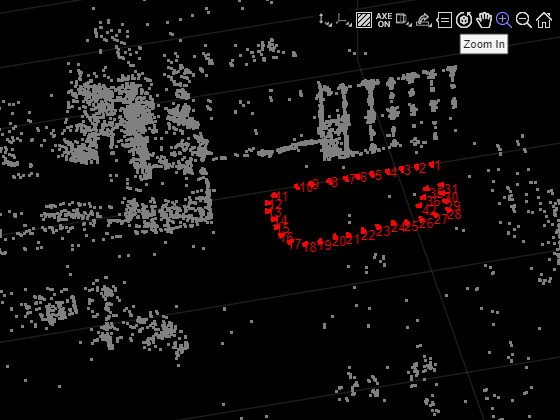

% Display camera poses.
camPoses = poses(vSet);
figure;
plotCamera(camPoses, Size=0.1);
hold on

% Exclude noisy 3-D points.
goodIdx = (reprojectionErrors < 5);

% Display the 3-D points.
pcshow(xyzPoints(goodIdx, :), [0.5 0.5 0.5], VerticalAxis='y', VerticalAxisDir='down', MarkerSize= 45);
grid on
hold off